# Multilevel mediation 

### Mediation analysis: The basics

Mediation is a useful tool for connecting variables into pathways. It extends the idea of a simple association between two variables (let's call them ***x*** and ***y****)* to a pathway involving three (or more) variables.  Let's write the association ***x*** predicts ***y*** like this: **[ *****x -> y ].***  With mediation analysis, you can build a model of associations among three variables, i.e., **[ *****x *****->***** m *****->***** y *****]**. ***m*** is a mediator, a variable that explains some or all of the relationship between ***x ***and ***y***.  

Mediation models are especially useful for developing models in which an association between two variables is transmitted via a third variable. For example, the effects of a psychological stressor (x) on heart rate (y) may be mediated by activity in brain systems responsible for threat. The stressor activates the brain, and the brain in turn controls the heart.  

In mediation analysis, ***x*** is called the initial variable. it will often be an experimental variable (IV) that is experimentally manipulated, but it doesn't have to be.  ***y*** is called the outcome variable, and it is usually the endpoint that one is interested in explaining. m is the mediator, and is usually a variable that is thought to be important for transmitting the effect of ***x*** on ***y, ***or on the "causal path" from ***x ***to*** y. ***It is also possible to include multiple initial variables, multiple mediators, and other covariates in such models. The broader family that the [ *x *->* m *->* y *] model belongs to is called **path models****.**

Here are some other examples. Exercise may improve memory via neurogenesis.  Exercise causes new neurons to be generated in the brain, which helps the brain form new memories more efficiently.  here, ***x*** is exercise, ***m*** is neurogenesis, and ***y*** is memory. Smoking (***x***) may lead to premature death (***y***) via increased rates of cancer (***m***). 

**A note on causality**. Mediation models of the type we explore here (and path models more generally) are build on linear regression, with the same assumptions and limitations of other linear models. It is a directional model: As with a standard multiple regression model, we are explaining ***y*** as a function of ***x*** and ***m***. And, as with standard regression, the presence of a statistical association does not provide direct information on causality. The observed relationships could, in principle, be caused by other variables that are not included in the model (i.e., lurking variables or common causes), and/or the direction of causality can be reversed from how you've formulated it in the model.  Experimental manipulation of variables can provide stronger evidence for causal associations, and sometimes both ***x*** and ***m*** are experimentally manipulated. However, when variables are observed rather than manipulated, statistical associations very rarely provide strong information about causality. 

### Multilevel mediation

In the standard mediation model, each of X, M, and Y are vectors with one observation per person. Thus, the individual participant is the unit of observation. When this is the case, we'll call this a **single-level** mediation. 99% or so of the mediation analyses in the literature are single-level models.  For example, X can include a vector of individuals who are either smokers (coded as 1) or non-smokers (coded as -1), and we include measures of both the incidence of cancer (M) and survival time (Y) for each person.

What happens if we have repeated observations of X, Y, and M within a person?  This allows us to estimate the Path a, Path b, and a*b effects within each person.  This allows each person "to serve as their own control", and eliminates a number of person-level confounds and noise. For example, in our cancer example above, people will likely vary in their diet, and diet could be correlated with smoking, introducing a potential confound (or "3rd variable") and at the least an additional source of uncontrolled noise.  In a mulitlevel model, we can estimate the effect within-person, and test the significance of the path coefficients across individuals, treating participant as a random effect. This reduces the chances that the mediation effect is related to a 3rd variable, and allows us to generalize the effect across a population with a range of diets (and other person-level characteristics). This can often dramatically increase the power and validity of a mediation model.

In addition, with multilevel mediation, we can include person-level covariates in the model as well. For example, we can test whether diet moderates (influences) the effects of smoking on cancer (Path a), the effects of cancer on mortality (Path b), or the mediation (a*b) effect.  This is called moderated mediation. Thus, multilevel mediation allows us to include two kinds of variables in the same model: within-person variables that are measured for each person, and between-person (or person-level) variables that are measured once for a person. We can make inferences on the within-person mediation effect and test whether it generalizes over or is moderated by person-level characteristics. 

Single-level (standard) and multilevel mediation with all of these variations is implemented in the [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox).

### Brain mediators and mediation effect parametric mapping (MEPM)

Multilevel mediation models are fairly rare in the social sciences, but in fMRI studies of cognitive and affective tasks, they are a natural fit.  We often manipulate tasks and observe both brain activity and behavioral responses (e.g., ratings or performance) within-person across time.  This makes multilevel mediation a natural fit to analyze experimental effects on the brain and their relationships with behavior in a single model. We can even add person-level characteristics like patient status or personality into the model as well.  

The mediation model we'll explore in this tutorial looks like this:

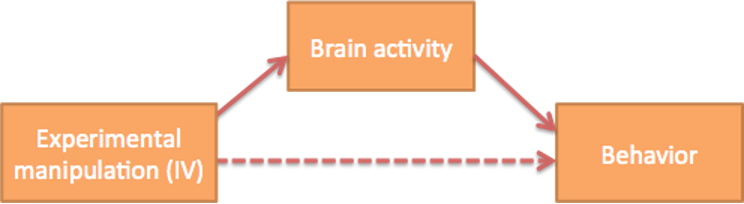		

		    X                                                M                                                   Y

X represents the task condition -- e.g., in our example below, the temperature of a hot stimulus applied to the skin. It is often coded with 1 or -1 ("effects coding") when there are two conditions, but can be coded with linear contrast codes or other numerical values when there are more than two conditions. M represents fMRI activity.  Y represents a behavioral outcome of interest.

Here, for our neuroimaging multilevel mediation tutorial, we'll extend this in two ways:

- We'll search over brain voxels, testing each voxel in an fMRI study as a mediator one at a time. We'll then save maps of how strong the mediation effect is.

- We'll change the unit of observation from the participant to conditions within-participant.  This is possible because in fMRI, we typically we vary X within-person by including different experimental tasks that might impact M and Y. We can also observe fMRI acitivity (M) and behavior (Y) as they vary within-person.  When we model these within-person relationships and perform statistical tests to generalize the associations to a population of individuals, we are performing multilevel mediation.   				

The [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox) will perform both single- and multilevel mediation. The function **mediation.m** can operate on any type of input data (behavior, psychosocial measures, physiology, brain, genetics, etc.), and will run both single and multilevel mediation depending on the input data.

The toolbox also has special functions for running mediation on each voxel in a neuroimaging dataset (single or multilevel) and saving maps of mediation effects:

### About the dataset

This dataset includes 33 participants, each with brain responses to six levels

of heat (44.3 - 49.3 degrees C in one degree increments, which generally span the range from non-painful to painful). For each participant, a .nii image is included with 6 brain volumes (one per intensity level, in ascending order). These model the average activity during painful stimulation, assuming the standard canonical HRF, and were estimated using first-level models in SPM8. A metadata file includes the temperature and average pain rating per subject per temperature. 

Aspects of this data appear in these papers, among others:

[Wager, T.D., Atlas, L.T., Lindquist, M.A., Roy, M., Choong-Wan, W., Kross, E. (2013). An fMRI-Based Neurologic Signature of Physical Pain. The New England Journal of Medicine. 368:1388-1397](https://www.nejm.org/doi/full/10.1056/nejmoa1204471)

(This study is Study 2 of the paper).

[Woo, C. -W., Roy, M., Buhle, J. T. & Wager, T. D. (2015). Distinct brain systems mediate the effects of nociceptive input and self-regulation on pain. PLOS Biology. 13(1):e1002036. doi:10.1371/journal.pbio.1002036](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.1002036)

[Lindquist, Martin A., Anjali Krishnan, Marina López-Solà, Marieke Jepma, Choong-Wan Woo, Leonie Koban, Mathieu Roy, et al. 2017. Group-Regularized Individual Prediction: Theory and Application to Pain. NeuroImage. 145:274-287.](https://www.sciencedirect.com/science/article/pii/S1053811915009982) 

[Stephan Geuter, Elizabeth A Reynolds Losin, Mathieu Roy, Lauren Y Atlas, Liane Schmidt, Anjali Krishnan, Leonie Koban, Tor D Wager, Martin A Lindquist, Multiple Brain Networks Mediating Stimulus–Pain Relationships in Humans, Cerebral Cortex, Volume 30, Issue 7, July 2020, Pages 4204–4219.](https://academic.oup.com/cercor/article/30/7/4204/5811924?login=true)

The dataset is available in CANlab Core toolbox under "Sample_Datasets/Woo_2015_PlosBio_BMRK3_pain_6levels". BMRK3 is the CANlab study code for this study. It was collected by Mathieu Roy, Jason Buhle, and research assistants in the CANlab.

### Using the dataset to demonstrate mulitlevel mediation

This dataset provides a lightweight, minimally viable dataset to demonstrate multilevel mediation. Usually, a mulitlevel mediation dataset would include more than 6 images per person -- for example, it might include trial-level data (as in Atlas et al. 2010, 2014; Koban et al. 2019) or full time series data (as in Wager et al. 2009).

Here, the variable **temperatures** will serve as the initial variable (X), **ratings** will serve as the outcome variable (Y), and brain images, whose names are stored in a variable called **single_trial_image_names**, will serve as the mediator (M).  Thus, the analysis will search over brain voxels and test whether each voxel's response during pain mediates the effects of temperature on pain ratings: 

***[temp (X) -> brain activity during pain (M) -> pain ratings (Y)]***

The function `mediation_brain_multilevel` will take in a set of image names in place of either X, Y, or M. 

The format is that each of X, Y, and M are cell arrays, with one cell per subject.  Each cell should contain either a column vector of values (for numeric variables) or a list of image names or 4D image for brain image inputs.

### Load the dataset

Locally or from the web					

metadata_file = which('bmrk3_6levels_metadata.mat');
metadata_file

metadata_file = '/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Woo_2015_PlosBio_BMRK3_pain_6levels/bmrk3_6levels_metadata.mat'


if isempty(metadata_file)

    disp('You need the dataset Woo_2015_PlosBio_BMRK3_pain_6levels on your Matlab path.')
    disp('This is in the CANlab Core toolbox.')
    error('Check path and files.')
end

load(metadata_file);

% Re-find local path names for brain images
M = single_trial_image_names;

dir_old = fileparts(M{1});
dir_new = fileparts(metadata_file);

for i = 1:length(M), M{i} = strrep(M{i}, dir_old, dir_new); end

X = temperatures;
Y = ratings;

whos X Y M

  Name      Size            Bytes  Class    Attributes

  M         1x33            12342  cell               
  X         1x33             5016  cell               
  Y         1x33             5016  cell               



### Set up and run multilevel mediation

Most of the heavy lifting is done here. There are three steps:

- Create a mediation directory to save output, and go there

- Configure setup options in a SETUP structure

- Run mediation (this will save files to disk)

*Note*: The mask will likely have to be resliced (resampled and interpolated) to match the origin and dimensions of the brain dataset.

mkdir mediation_results
cd mediation_results


Will show slices.
Will print tables.
Saving log file: X-M_pvals_003_k5_noprune_log.txt
Other key results in: X-M_pvals_003_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.


Error using check_valid_imagename (line 42)
Cannot find image:
X-M_pvals.img


Error in iimg_multi_threshold (line 182)
    inname = check_valid_imagename(inname, 1);

Error in 

Will show slices.
Will print tables.
Saving log file: M-Y_pvals_005_k5_noprune_log.txt
Other key results in: M-Y_pvals_005_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0050 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.



iimg_multi_threshold viewer
Showing positive or negative: neg
Overlay is: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0050 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.


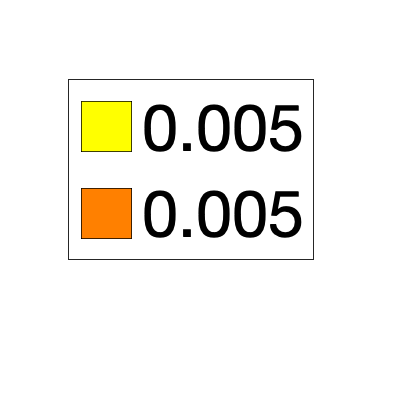

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033



Summary of output images:
M-Y_pvals.img
Results clusters clpos and clneg are returned for the LAST image in this set.
 
Printing Tables.
 
Z field contains: Mediation b effect (shown in maxstat)
 
Name	index	x	y	z	corr	voxels	volume_mm3	maxstat	snr_avgts(d)	minsnr	maxsnr	numpos	power80	partialr_with_y	partialr_p	Za_max	Pa_max	Zb_max	Pb_max	Zab_max	Pab_max	num_sig_voxels	
a	  1	-24	-38	-38	NaN	  8	 64	6.78	-0.55	-0.77	-0.24	  2	 54	NaN	NaN	2.61	0.0089	3.25	0.0011	1.54	0.12	
b	  2	-20	-60	-28	NaN	267	2136	8.40	0.83	-0.92	1.82	  6	 25	NaN	NaN	5.24	0.0000	3.69	0.0002	2.82	0.0048	
c	  3	 -2	-62	-14	NaN	 17	136	6.72	0.40	0.30	0.46	  4	101	NaN	NaN	4.38	0.0000	3.24	0.0012	2.70	0.0069	
d	  4	 20	 -4	-14	NaN	 12	 96	6.80	1.32	0.72	1.76	  6	 11	NaN	NaN	4.94	0.0000	3.26	0.0011	1.78	0.07	
e	  5	 50	 30	  6	NaN	  7	 56	6.12	0.22	-0.16	0.45	  5	346	NaN	NaN	3.05	0.0023	3.06	0.0022	2.41	0.02	
f	  6	-62	  2	  8	NaN	 16	128	6.47	1.02	0.95	1.18	  6	 17	NaN	NaN	4.24	0.0000	3.17	0.0015	2.60	0.0092	
g	  7	 3

Saving image of slices: orth_M-Y_pvals_005_k5_noprune_coronal.png


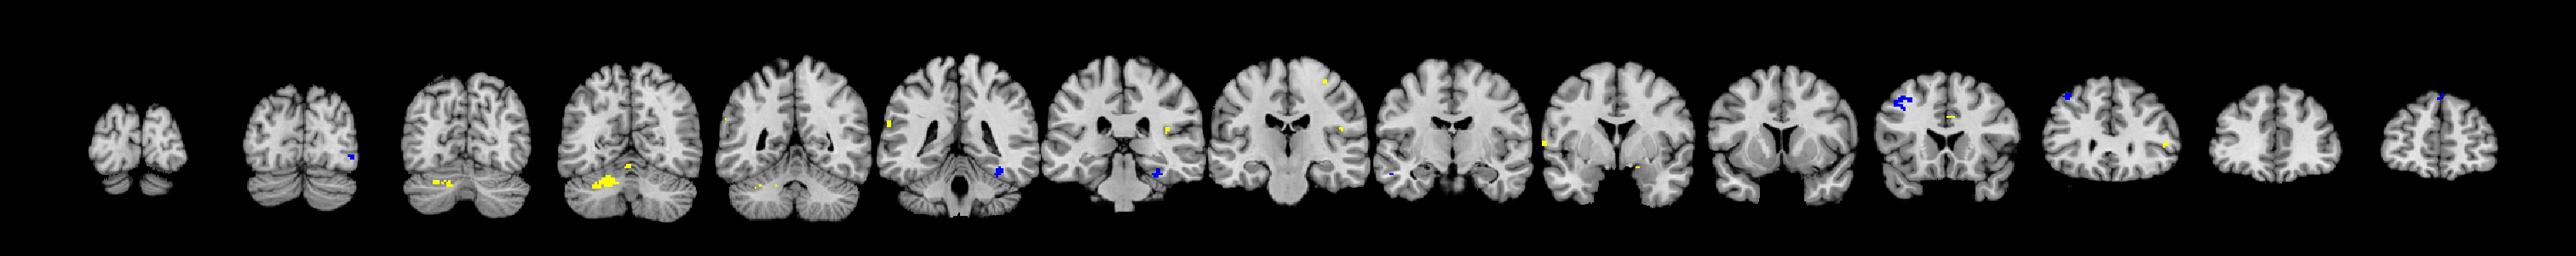

Saving image of slices: orth_M-Y_pvals_005_k5_noprune_sagittal.png


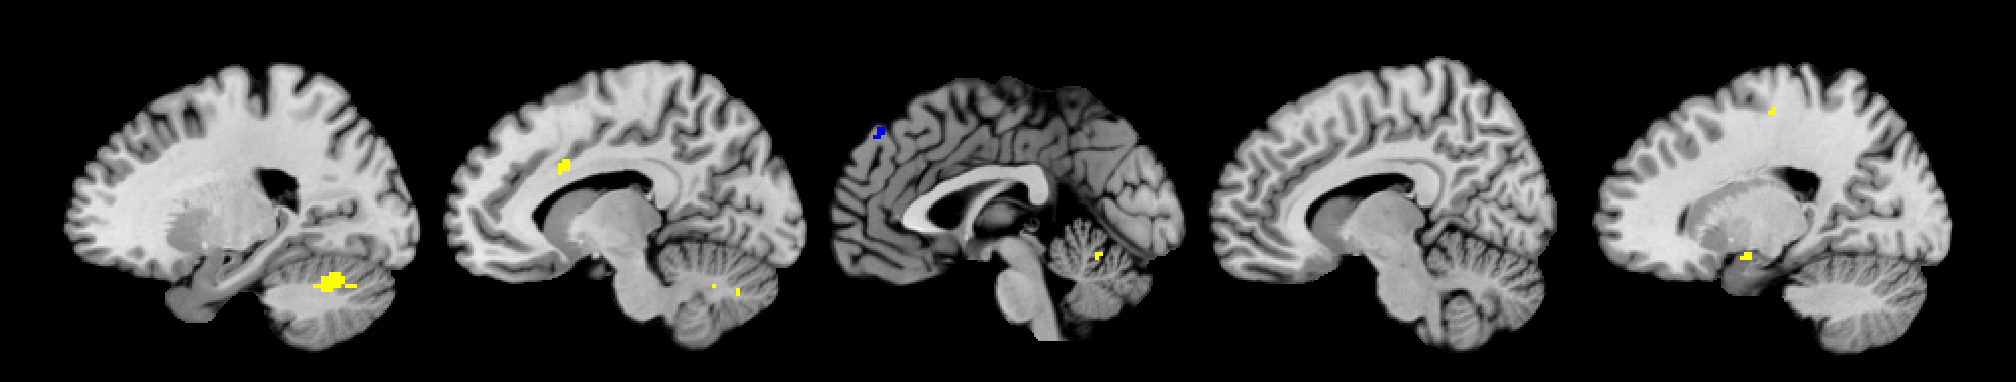

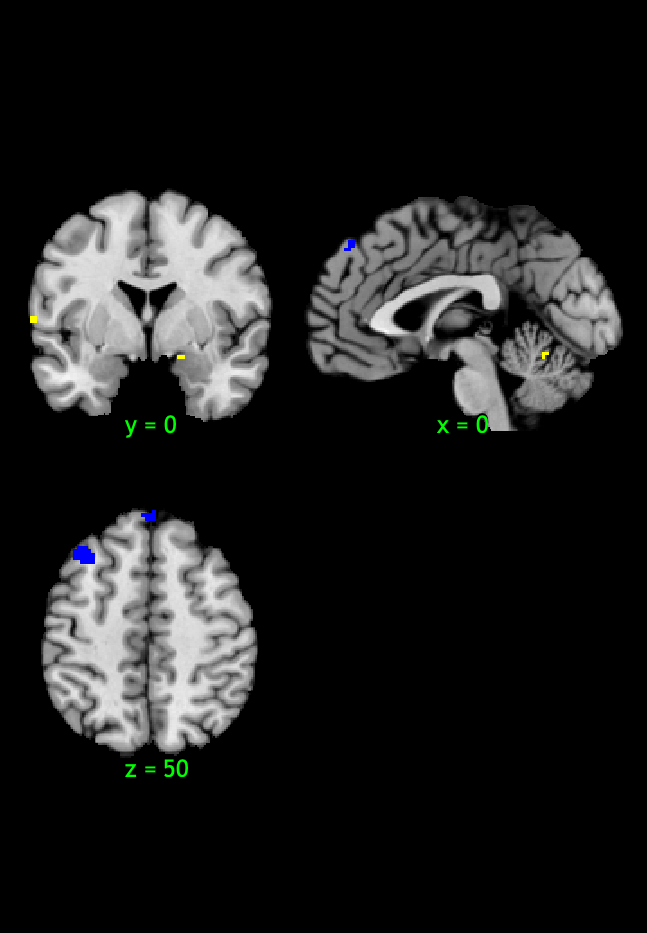

Saving image of slices: orth_M-Y_pvals_005_k5_noprune_axial.png


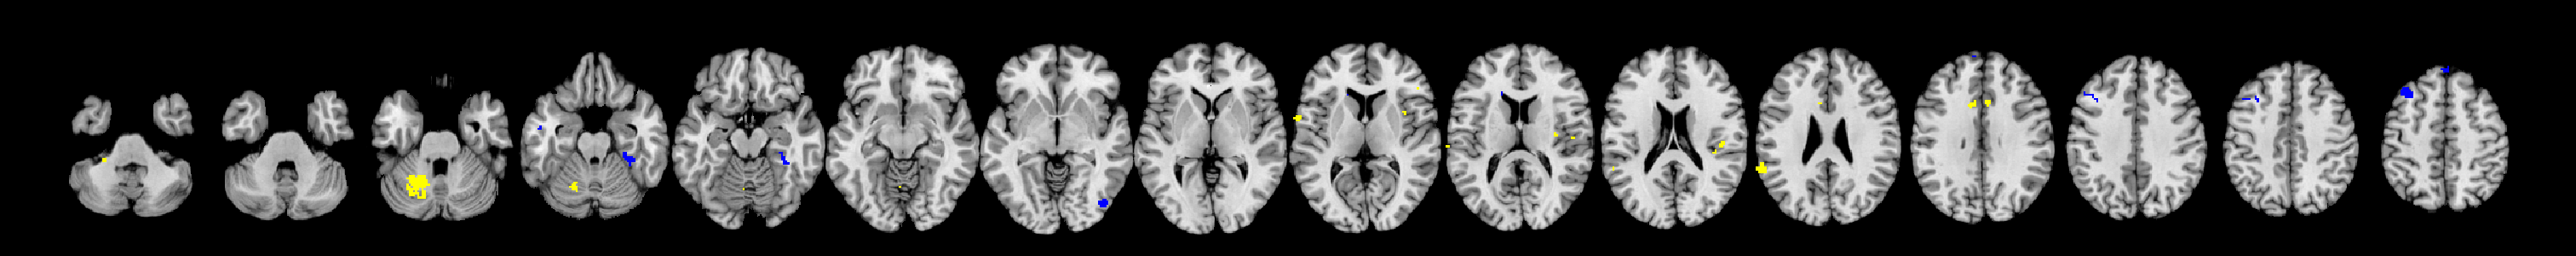

SETUP.mask = which('gray_matter_mask.nii');
SETUP.preprocX = 0;
SETUP.preprocY = 0;
SETUP.preprocM = 0;

Will show slices.


Will print tables.
Saving log file: X-M-Y_pvals_005_k5_noprune_log.txt
Other key results in: X-M-Y_pvals_005_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0050 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.



iimg_multi_threshold viewer
Showing positive or negative: neg
Overlay is: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0050 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.


Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033

Extracting image data for significant clusters. No clusters to extract.


Summary of output images:
X-M-Y_pvals.img
Results clusters clpos and clneg are returned for the LAST image in this set.
 
Printing Tables.
Full tables can only be printed if valid data are extracted.
I did not find valid images to extract from, so I'm printing
abbreviated tables.
 
Positive effects
 
Z field contains: Mediation ab effect (shown in maxstat)
 
Name	index	x	y	z	corr	voxels	volume_mm3	maxstat	snr_avgts(d)	minsnr	maxsnr	numpos	power80	
Ctx_TGv_R	  1	 26	 -6	-40	NaN	  6	 48	6.37	-0.44	-0.51	-0.39	  3	 83	
Cblm_VI_L	  2	-20	-60	-26	NaN	  7	 56	5.67	0.78	-0.17	1.12	  4	 28	
Ctx_TE1m_L	  3	-60	-26	-20	NaN	 11	 88	6.92	0.26	0.15	0.34	  3	234	
Ctx_6r_L	  4	-58	  4	  4	NaN	 26	208	6.99	1.10	1.00	1.39	  6	 15	
Ctx_FOP4_R	  5	 38	 10	  6	NaN	 34	272	8.93	0.27	-0.27	1.91	  5	218	
Ctx_43_R	  6	 60	  2	 10	NaN	 18	144	7.35	1.72	1.39	2.25	  6	  7	
Ctx_IFSa_L	  7	-54	 30	 12	NaN	  6	 48	6.16	-0.57	-0.71	-0.50	  1	 50	
Ctx_PFop_L	  8	-64	-26	 18	NaN	  6	 48	6.39	0.91	0.80	0.99	  5	 21	
Ct

Saving image of slices: orth_X-M-Y_pvals_005_k5_noprune_coronal.png


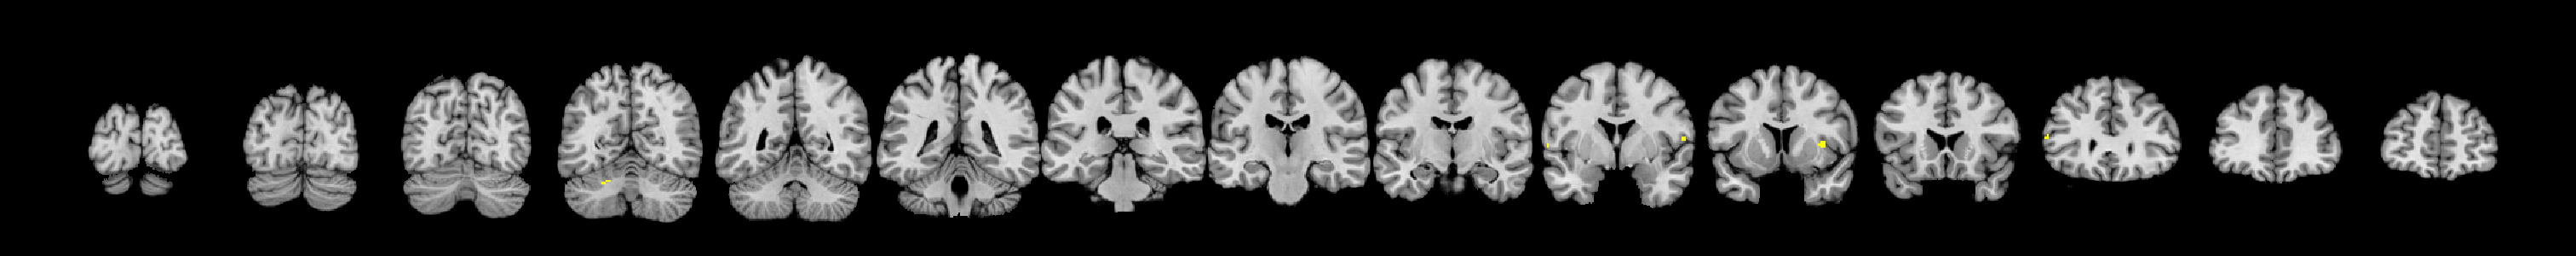

Saving image of slices: orth_X-M-Y_pvals_005_k5_noprune_sagittal.png


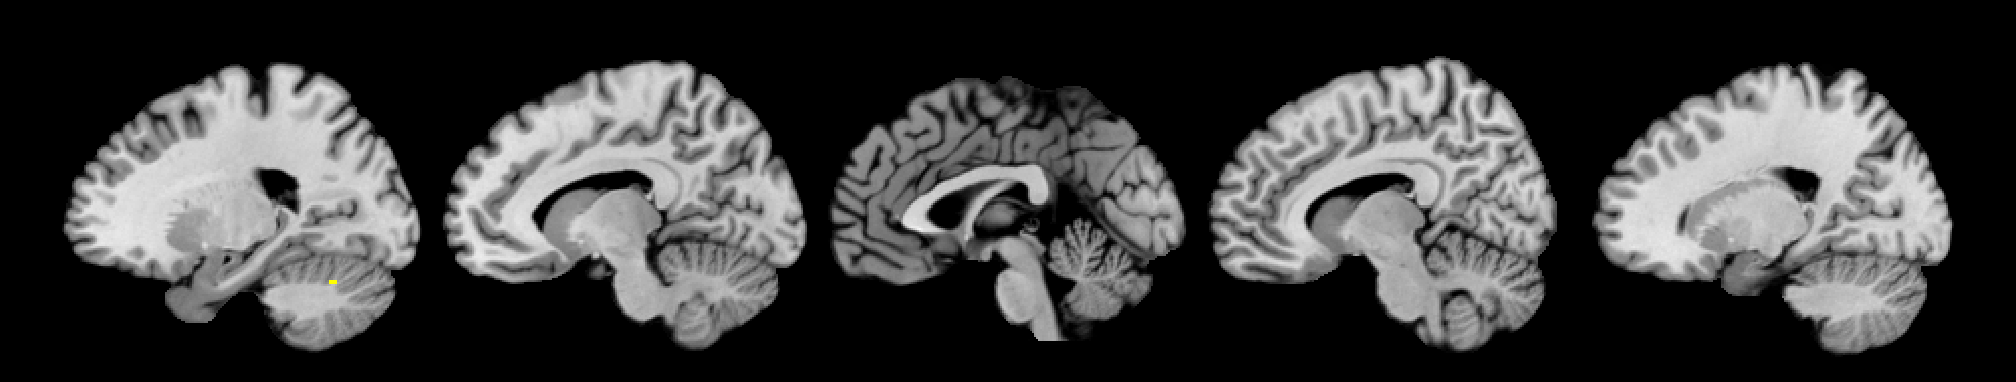

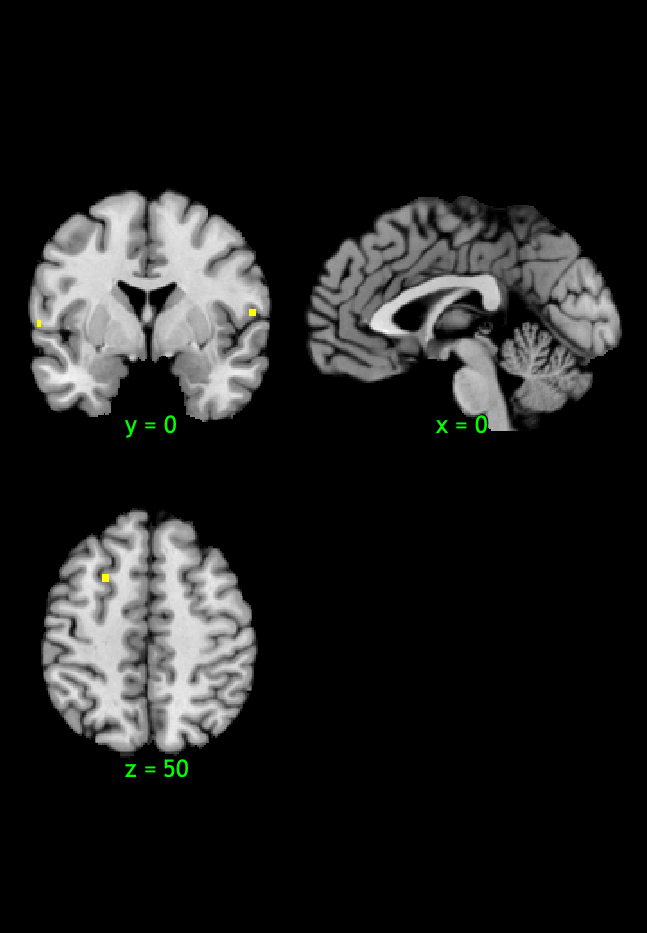

Saving image of slices: orth_X-M-Y_pvals_005_k5_noprune_axial.png


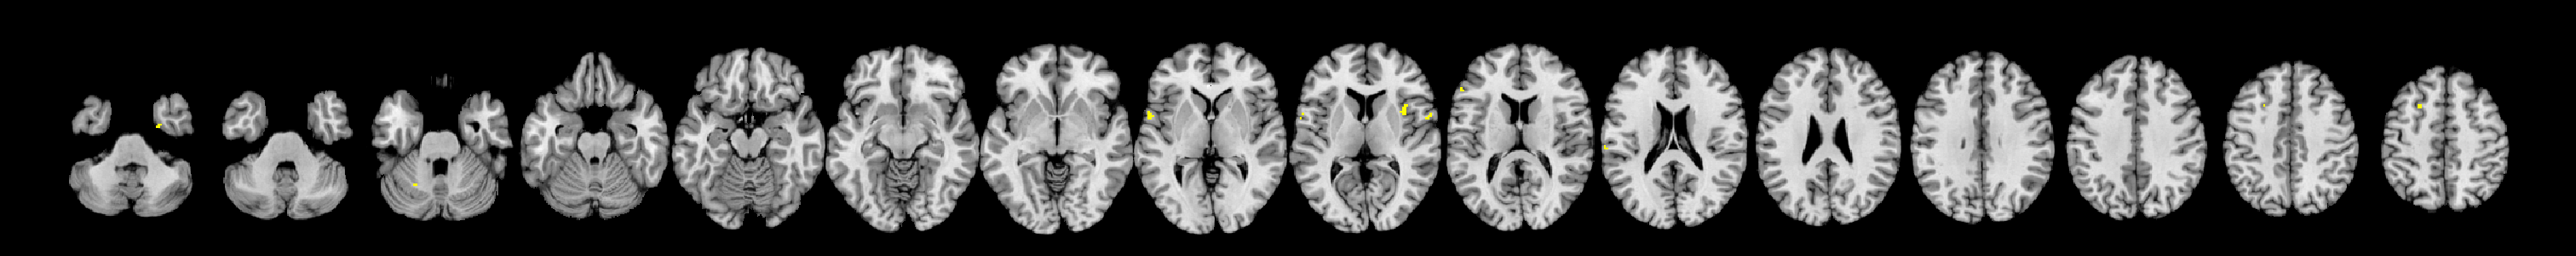


% mediation_brain_multilevel(X, Y, M, [other inputs])
mediation_brain_multilevel(temperatures, ratings, single_trial_image_names, SETUP);


`mediation_brain_multilevel `saves a SETUP file with the input variables and estimated results maps for all the relevant effects. You can save the files in directory and use them to make tables and figures of results at any time later. Here are some of the key files:

X-M_effect.img

M-Y_effect.img, 

M-Y_indiv_effect.hdr

M-Y_indiv_effect.img

M-Y_indiv_ste.hdr

M-Y_indiv_ste.img

M-Y_pvals.hdr

M-Y_pvals.img

M-Y_pvals_005_k5_noprune_log.txt

M-Y_pvals_005_k5_noprune_results.txt

M-Y_ste.hdr

M-Y_ste.img

X-M-Y_effect.hdr

X-M-Y_effect.img

X-M-Y_indiv_effect.hdr

X-M-Y_indiv_effect.img

X-M-Y_indiv_ste.hdr

X-M-Y_indiv_ste.img

X-M-Y_pvals.hdr

X-M-Y_pvals.img

X-M-Y_pvals_005_k5_noprune_log.txt

X-M-Y_pvals_005_k5_noprune_results.txt

X-M-Y_ste.hdr

X-M-Y_ste.img

X-M_indiv_effect.hdr

X-M_indiv_effect.img

X-M_indiv_ste.hdr

X-M_indiv_ste.img

X-M_pvals.hdr

X-M_pvals.img

X-M_ste.hdr

X-M_ste.img

X-Y_direct_effect.hdr

X-Y_direct_effect.img

X-Y_direct_indiv_effect.hdr

X-Y_direct_indiv_effect.img

X-Y_direct_indiv_ste.hdr

X-Y_direct_indiv_ste.img

X-Y_direct_pvals.hdr

X-Y_direct_pvals.img

X-Y_direct_ste.hdr

X-Y_direct_ste.img

X-Y_total_effect.hdr

X-Y_total_effect.img

X-Y_total_indiv_effect.hdr

X-Y_total_indiv_effect.img

X-Y_total_indiv_ste.hdr

X-Y_total_indiv_ste.img

X-Y_total_pvals.hdr

X-Y_total_pvals.img

X-Y_total_ste.hdr

X-Y_total_ste.img

cl_M-Y_pvals_005_k5_noprune.mat

cl_X-M-Y_pvals_005_k5_noprune.mat

mask.hdr

mask.img

mediation_SETUP.mat

# Get and save results 

Once you've completed a successful run of `mediation_brain_multilevel`, you can go to the results directory and examine the results.  The goal of this section is to construct and save:

- Figures showing significant regions

- Significant "blobs" (clusters) with extracted data (cl* below)

- Tables of significant regions with mediation statistics

We can get results on significant regions for each of the Path a, Path b, and Path a*b (mediation effect) maps.

- The*** Path a*** map tests the effect of X (temperature) on M (brain responses)

- The ***Path b*** map tests the effect of M (brain responses) on Y (ratings) controlling for X (temperature)

- The ***Path a*b*** (mediation) map tests the product of a and b, or (equivalently) whether M (brain) explains a significant amount of the covariance between X and Y.

For a single-level mediation, the thresholded ***Path a*b ***map (showing signifcant voxels) will always include a subset of the voxels significant in the ***Path a ******and****** Path b ***maps. 

For a multilevel mediation, this is not necessarily the case. This is because the significance of the a*b mediation effect is based on the strength of the average a effect, the average b effect, and the covariance between them. This is explained by [Kenny, Korchmaros, and Bolger (2003)](https://psycnet.apa.org/buy/2003-06499-003), a seminal paper on mulitlevel mediation. It's discussed in relation to brain maps in [Atlas et al. 2010](https://www.jneurosci.org/content/30/39/12964.short).  

This means that you might be interested in looking at each of the maps, as each provides a different and complimentary piece of information.

#### Choose a threshold

We'll need to specify a significance threshold, entered as a P-value threshold. The function below chooses a threshold that satisfies FDR on average across the Path a, b, and a*b maps. 

There are other thresholding options as well.  We could also choose an uncorrected P-value threshold to be entered into the `mediation_brain_results `function below. 

SETUP = mediation_brain_corrected_threshold('fdr');

This gives us an equivalent P-value to satisfy FDR-corrected at q < 0.05 on average across the 3 maps, which is stored in SETUP.fdr_p_thresh.  It will be *Inf* if there is not enough signal to meet the threshold.

*Note*: P-values are always two-tailed, unlike SPM P-values, which are one-tailed. So P < 0.002 here is equivalent to P < 0.001 using SPM.

**Multi-thresholding and 'pruned' significant regions**

We can choose a *series* of P-value thresholds if we want to save clusters ('blobs') where at least one voxel meets the most stringent threshold, but show continguous voxels in the cluster down to the most liberal threshold. We call this 'pruned' clusters, because we're thresholding a liberal display threshold but 'pruning' the set of significant regions so that each region has at least one voxel at the most stringent (often corrected) threshold. This can be useful for display and in particular for showing the extent of regions around the most stringent value.  For example, entering these options into `mediation_brain_results `will show us clusters where at least one voxel is FDR-corrected at q < 0.05 (map-wise), but we'll see the extent of each blob down to p < 0.005 as long as there are 3 contiguous voxels at that threshold (that are also contiguous with FDR-corrected results) and down to p < 0.01 uncorrected as long as there are at least 10 contiguous voxels. 

**Other preliminary stuff**

Let's define some variables that we can use to print nice headers in the report:

dashes = '----------------------------------------------';
printstr = @(dashes) disp(dashes);
printhdr = @(str) fprintf('%s\%s\n%s\n%s\n%s\n', dashes, dashes, str, dashes, dashes);


[clp, cln, clpp, clnn] = mediation_brain_results('a', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

[clp, cln, clpp, clnn] = mediation_brain_results('b', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

[clp, cln, clpp, clnn] = mediation_brain_results('ab', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

Here is another way of printing a basic table with region labels and region-level stats, using CANlab object-oriented tools.  We first convert the clusters structure (clp{1}) to a *region* object, and then we can use region-class methods like *table()*.  

pos_regions = cluster2region(clp{1});
table(pos_regions, 'nolegend');